# ABM4

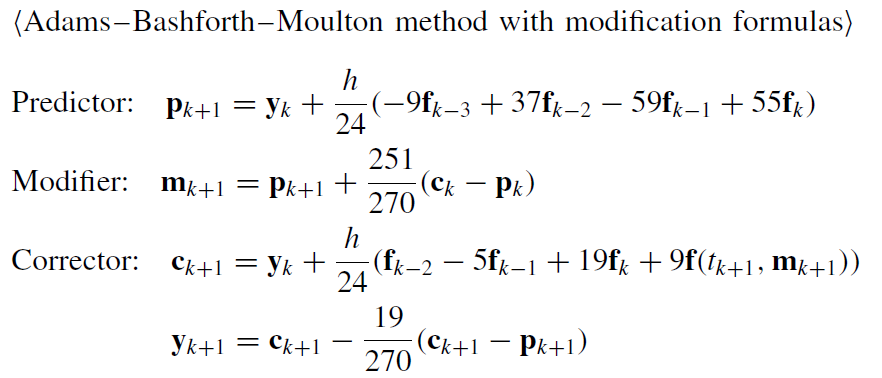

function [t,y] = odeABM4(f,y0,t0,tf,h)

    rtol=eps;
    MAX=1000;

    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0),n);
    [~,yTemp]=odeRK4(f,y0,t0,t0+3*h,h);
    y(:,1:4)=yTemp;
    fVp=zeros(length(y0),4);
    for k=1:4
        fVp(:,5-k)=f(t(k),y(:,k));
    end
    pkp=0;
    ckp=0;
    f3=f(t(1),y(:,1));%-3
    f2=f(t(2),y(:,2));%-2
    f1=f(t(3),y(:,3));%-1
    fi=f(t(4),y(:,4));%donde estoy
    
    for i=4:n-1
        yi=y(:,i)
        pk=yi+(h/24)*(-9*f3+37*f2-59*f1+55*fi); %predictor
        mk=pkp+(251/270)*(ckp-pkp); %modifier
        ck=yi+(h/24)*(f2-5*f1+19*fi+9*f(t(i+1),mk)) %corrector
        yi=ck-(19/270)*ck-pk; %y(:,i+1)
        f3=f2;%-3
        f2=f1;%-2
        f1=fi;%-1
        fi=f(t(i+1),yi);%donde estoy
    end

end